# Computer assignment 2

# Digital signal processing

## By:Hamidreza_Aliakbarykhoyi

810196514

## Question 1

in this part we should read giving voice that hase one tone noise on it trying to design a good filter to remove it and listen to it.

## part A

with code generated for fourier transform (attached to file)we use two operation on read signal which are fft() and fftshift() to plot frequency domain of signal and see the exact position of one tone noise added on signal.Before thet se listen to noisy voice with sound() so cause of noise the words can't be detected well.as shown in figure of fourier transform of noisy sound we have 2 spikes of single tone noise ,although we can't see original signal frequency domain in this figure versus noise but if you zoom in you can see some kine of amplitude rised in frequencyes around 0 and 8k.

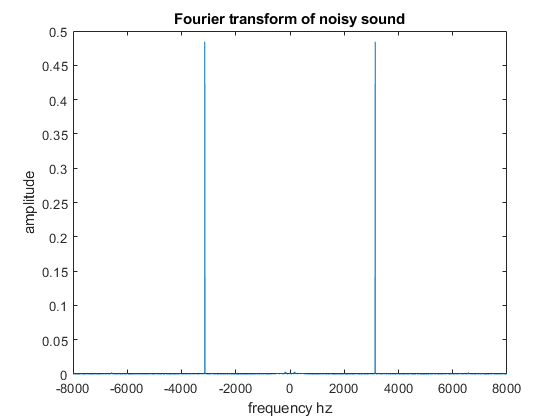

[NoisySound,Fs] = audioread('NoisySound.wav');
%sound(NoisySound,Fs);
FFTshift_noisysound=Fourier_Transform(NoisySound);
len=length(NoisySound);
F_deviation=Fs*(-len/2:len/2-1)/len;
figure
plot(F_deviation,FFTshift_noisysound);
title("Fourier transform of noisy sound");
xlabel("frequency hz");
ylabel("amplitude");

## Part B,C

to remove noise we need a band stop filter. because there is no critical and important information detected around noise and also because of setting least order to our filter we can set filter design parameters to have smooth filter.As seen in uploaded filter .m files i designed two band stop filter first is Equiripple and second is leastsquares.Equripple parameters are : Fpass1:2300 , Fstop1:2700,Fstop2:3600,Fpass2:3900 .I got 83 order to design it,but we can reduce it by making it smoother.In equripple phase has a linear form for its change.and in stop frequencyes we have -100db of decrease in main amplitude that it completly removes the single tone noise.Least squares has a benefit that we can set order by our self and so we can have a proper balance between order and filter design factors .In least squares we can see more phase changes per frequency than Equripple that means group delay of Equripple is better.so i used Equripple in rest of CA.

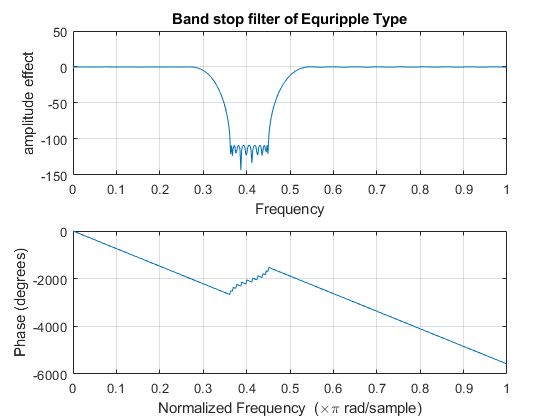

figure
freqz(BS_equiripple1);
title("Band stop filter of Equripple Type");
xlabel("Frequency");
ylabel("amplitude effect");

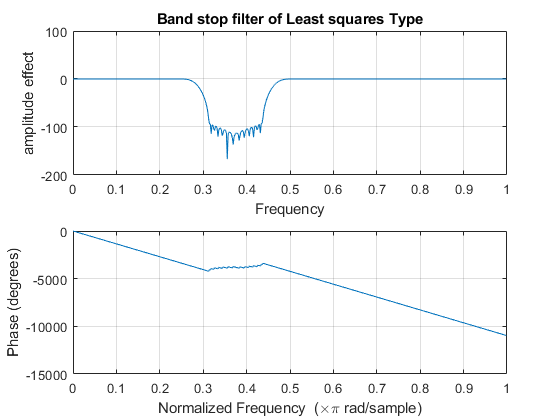

freqz(BS_leastsquares1);
title("Band stop filter of Least squares Type");
xlabel("Frequency");
ylabel("amplitude effect");

Noisyless_signal_equripple ...
    =filter(BandStopEquiripple,NoisySound);
Noisyless_signal_leastaquares ...
    =filter(BandStopleastsquar,NoisySound);
%sound(Noisyless_signal_leastaquares,Fs);
%sound(Noisyless_signal_equripple,Fs);
audiowrite('NoiseLess.wav',Noisyless_signal_equripple,Fs);

Useing Sound() we can heare and detect the words in voice easily so filter worked.

After filtering i made new .Wav file that has no noise and saved.

## part D

## 1

Noise_filtered voice has both low and hig frequencies and even both has important information in it.in this part we use lowpass filter to detect low fresuencies of voce which is more like to a Man's voice than a woman's.After that as you can result plotted in time domain shows that more frequent changes on it have changed ,alse that was what we expect because we remove high frequencies.For filtering it i used Equripple .after filtering i listened to voie that looks like more to a Man's voice as i mentioned before.

[NoiseLessWave,Fs] = audioread('NoiseLess.wav');

%sound(NoiseLessWave,Fs);
noiseless_lowpass_equripple= ...
    filter(LowPassEquiripple,NoiseLessWave);
%sound(noiseless_lowpass_equripple,Fs);

## 2

by filtering we can see we remove high frequencies and it is obvious due to see fast changing parts (high frequncy)have been removed.

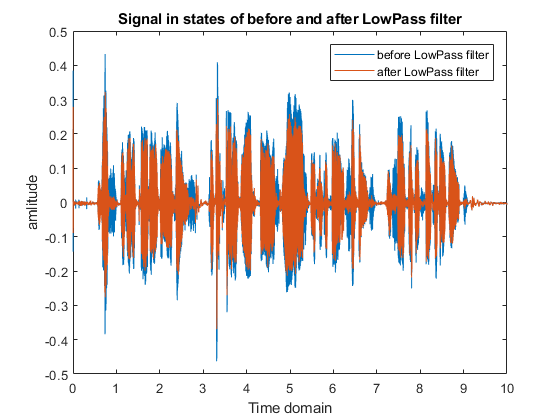

figure
plot((0:len-1)/Fs,NoiseLessWave)
hold on
plot((0:len-1)/Fs,noiseless_lowpass_equripple)
legend('before LowPass filter','after LowPass filter');
title("Signal in states of before and after LowPass filter");
xlabel("Time domain");
ylabel("amlitude");

## 3

In fourier of lowpassed_voice we can detect just low frequencyes.Due to result we can see that filter worked well and removed high frewuencies well.

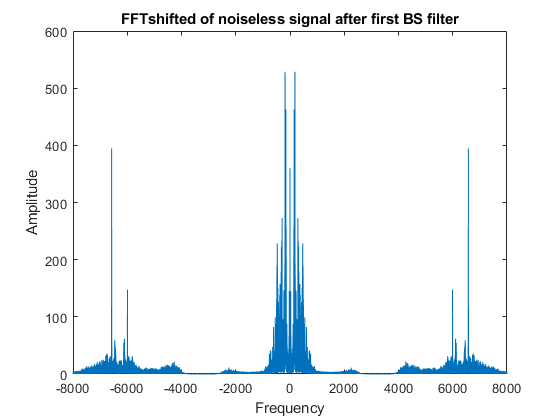

fftshift_NoiseLessWave= ...
    abs(fftshift(fft(NoiseLessWave)));
fftshift_NoiseLessWave_afterLP= ...
    abs(fftshift(fft(noiseless_lowpass_equripple)));
figure
plot(F_deviation,fftshift_NoiseLessWave);
title("FFTshifted of noiseless signal after first BS filter");
ylabel("Amplitude");
xlabel("Frequency");

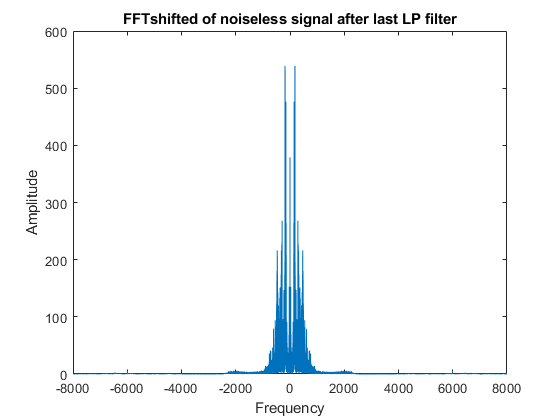

figure
plot(F_deviation,fftshift_NoiseLessWave_afterLP);
title("FFTshifted of noiseless signal after last LP filter");
ylabel("Amplitude");
xlabel("Frequency");

## 4

Frequency plot of low pass filter that designed shows a decrease in main amplitude of signal in frequencyes above 0.3pi adn also we have linear hase changes.

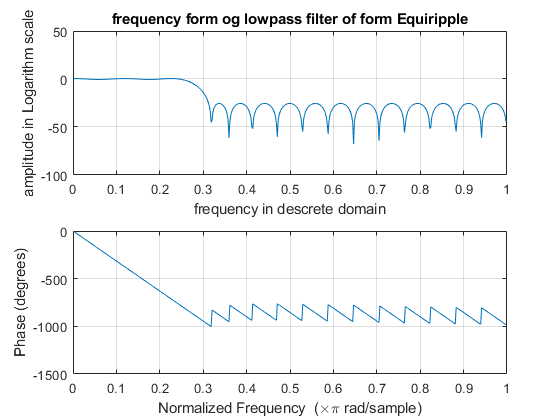

figure
freqz(lowpass_equiripple1);
title("frequency form og lowpass filter of form Equiripple")
xlabel("frequency in descrete domain")
ylabel("amplitude in Logarithm scale")

## part d_h

## 1

all 4 steps that we did in previous part should be done in this case in high pass filter designed that will show us high frequencyes.after playing filtered voice we see that it seems like a woman's voice than a man's.It was totally what we expected.

signal_filtered_BS_HP= ...
    filter(HighPass_butterworth,NoiseLessWave);
%sound(signal_filtered_BS_HP,Fs);
audiowrite('NoiseLess_BS&HP.wav',signal_filtered_BS_HP,Fs);

## 2

we plot both noiselees voice and signal came out after high pass filter it shows high frequency changes of signal that is what we expected and as we can detect in high frequencits energy distribution is less than low frequncy and that was expected because we hear a man is talking in voice so it shall have low frequencyes more.

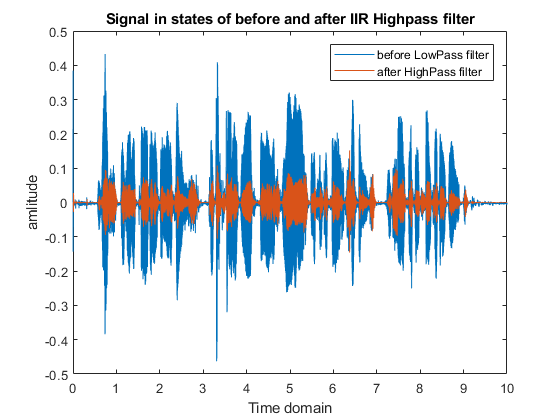

figure
plot((0:len-1)/Fs,NoiseLessWave)
hold on
plot((0:len-1)/Fs,signal_filtered_BS_HP)
legend('before LowPass filter','after HighPass filter');
title("Signal in states of before and after IIR Highpass filter");
xlabel("Time domain");
ylabel("amlitude");

## 3

after filtering and catching high frequencyes we plot in freuency domain and it can be detected that filter is working well and just high frequncyes remained.

 fftshift_NoiseLessWave= ...
    abs(fftshift(fft(NoiseLessWave)));
fftshift_NoiseLessWave_afterHP= ...
    abs(fftshift(fft(signal_filtered_BS_HP)));
figure
plot(F_deviation,fftshift_NoiseLessWave);
title("FFTshifted of noiseless signal after first BS filter");
ylabel("Amplitude");
xlabel("Frequency");

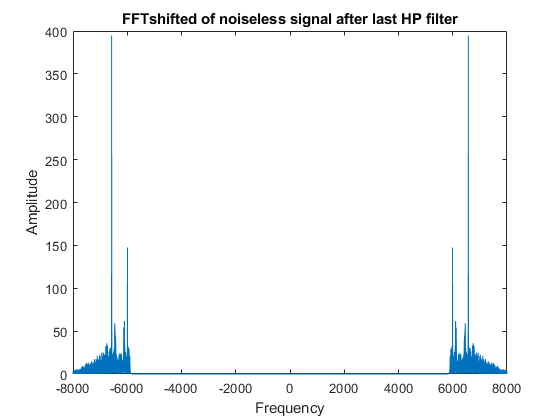

figure
plot(F_deviation,fftshift_NoiseLessWave_afterHP);
title("FFTshifted of noiseless signal after last HP filter");
ylabel("Amplitude");
xlabel("Frequency");

## 4

we plot frequncy response of filter and as we can see phase changes is not linear any more but in passing frequencies it is sort of linear and filter decrease main magnitude of signal by 4000dB that is much more that filters in last part.

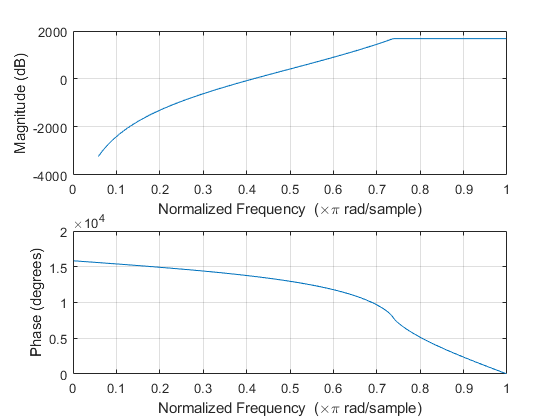

figure
freqz(HighPass_butterWorth);

## Question 2

we are to design an IIR filter that is Band Stop.with given parameters we design filter.

in frequncy plot we can see maximum 200 degrees in passing frequencyes and decrease of 40 dB in stopping frequencyes.It is obvious from plot that we have linear phase filter that all zeros and ploes are in unit circle so it is a minimum phase filter.

group delay plot shows the delay in samples per frequency that filter is being used.

for example in frequency of 15 we have 21 samples delay.

Note:

I get sero pole plot and group delay plot from filter design tool bax which had these kind of outputs.

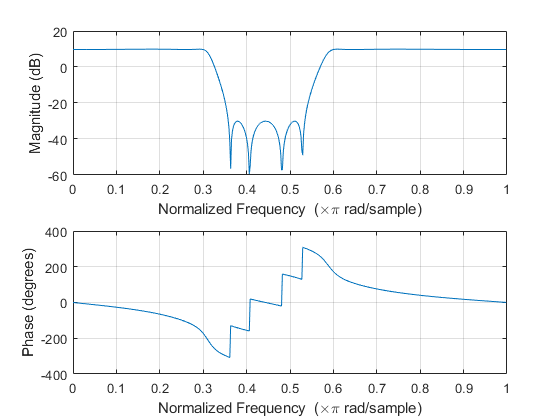

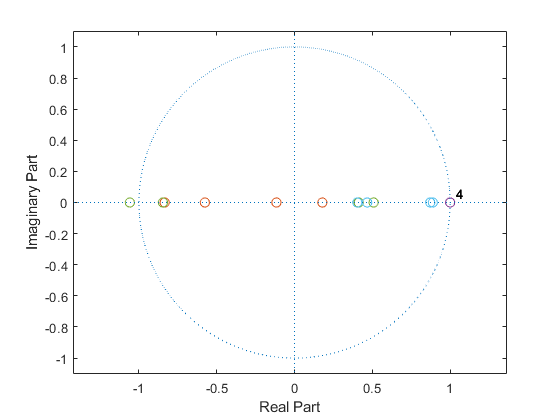

figure
freqz(BandStop_IIR);

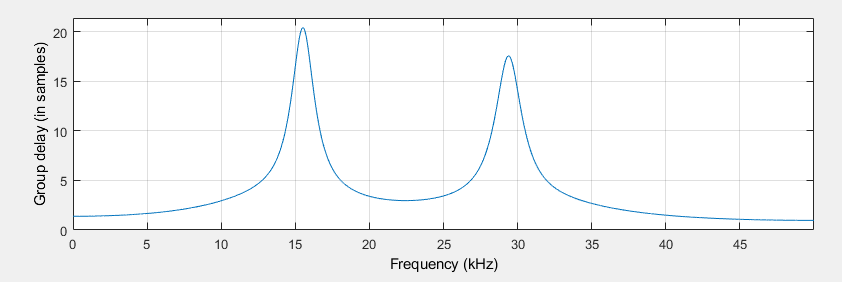

group delay

and polezero: